% %%%%%% 1
% alpha= 1 + mod(509,3);
% 
% fc = 10;
% fs = 720;
% Wp = 10/360;
% Ws = 20/360;
% 
% [n,Wn] = buttord(Wp,Ws,3,40);
% 
% [b,a] = butter(n,Wn);
% sys= tf(b,a,1/720)
% figure
% pzmap(sys)
% title('Pole-Zero Plot');
% grid on
% 
% f=linspace(0,50,100);
% figure
% [Mag,phase]=bode(sys,2*pi*f);
% subplot(2,1,1)
% plot(f,db(squeeze(Mag)),'LineWidth',2);
% xlabel('Frequency');
% ylabel('Magnitude(dB)')
% title('Bode Plot');
% grid on
% 
% subplot(2,1,2)
% plot(f,squeeze(phase),'LineWidth',2);
% xlabel('Frequency');
% ylabel('Phase')
% grid on
% 
% 
% 
% % Define the time vector for 1 second
% t = 0:1/fs:1;
% impulse_response = impulse(sys, t);
% step_response = step(sys, t);
% 
% figure;
% plot(t, impulse_response, 'b', 'LineWidth', 2, 'DisplayName', 'Impulse Response');
% hold on;
% plot(t, step_response, 'r', 'LineWidth', 2, 'DisplayName', 'Step Response');
% xlabel('Time (s)');
% ylabel('Amplitude');
% title('Impulse Response and Step Response');
% legend('show');
% grid on;
% 

% %%%%%%% 2
% ecg_signal = load('C:\Users\Student\Documents\Amar\EXP-6\ECG_Data.txt');
% filtered_signal = filter(b,a,ecg_signal);
% 
% t = (0:length(ecg_signal)-1) / fs;
% 
% % Plot the original and filtered ECG signals
% subplot(2,1,1);
% plot(t, ecg_signal);
% title('Original ECG Data');
% xlabel('Time (s)');
% ylabel('Amplitude');
% 
% subplot(2,1,2);
% plot(t, filtered_signal);
% title('Filtered ECG Data');
% xlabel('Time (s)');
% ylabel('Amplitude');

% %%%%%%% 3
% [y, Fs] = audioread('C:\Users\Student\Documents\Amar\EXP-6\instru3.wav');
% 
% figure;
% spectrogram(y, hamming(512), 256, 512, Fs, 'yaxis');
% title('Spectrogram of Original Audio');
% 
% % Design a Butterworth band-pass filter
% order = 10; % Filter order
% Fc1 = 500; % Lower cutoff frequency in Hz
% Fc2 = 3000; % Upper cutoff frequency in Hz
% 
% % Normalize cutoff frequencies
% Wn1 = Fc1 / (Fs/2);
% Wn2 = Fc2 / (Fs/2);
% 
% % Design the filter
% [b, a] = butter(order, [Wn1, Wn2], 'bandpass');
% 
% % Apply the filter to the audio signal
% filtered_signal = filter(b, a, y);
% 
% % Write the filtered signal to a new WAV file
% audiowrite('filtered_audio.wav', filtered_signal, Fs);
% 
% % Plot the spectrogram of the filtered signal
% figure;
% spectrogram(filtered_signal, hamming(512), 256, 512, Fs, 'yaxis');
% title('Spectrogram of Filtered Audio (Fundamental Frequency)');

%%%%%%% 4
alpha = 3;           
stopband_attenuation = 40;
Fs = 720; 
Fp = 10;  
Fstop = 20; 

% Calculate normalized cutoff frequencies (Wc and Ws)
Wc = 2 * Fp / Fs;
Ws = 2 * Fstop / Fs;

% Determine filter order (N) using the formula for Chebyshev Type I filter
[n, Wn] = cheb1ord(Wc, Ws, alpha, stopband_attenuation);

% Design the Chebyshev Type I filter
[z, p] = cheby1(n, alpha, Wn);
sos_chebyshev = tf(z, p, 1/Fs);

% Design the Butterworth filter as in the previous example
[n_butterworth, Wn_butterworth] = buttord(Wc, Ws, alpha, stopband_attenuation);
[z_butterworth, p_butterworth] = butter(n_butterworth, Wn_butterworth);
sos_butterworth = tf(z_butterworth, p_butterworth, 1/Fs);

% Compare the filter orders
fprintf('Chebyshev Type I Filter Order: %d\n', n);

Chebyshev Type I Filter Order: 5


fprintf('Butterworth Filter Order: %d\n', n_butterworth);

Butterworth Filter Order: 7


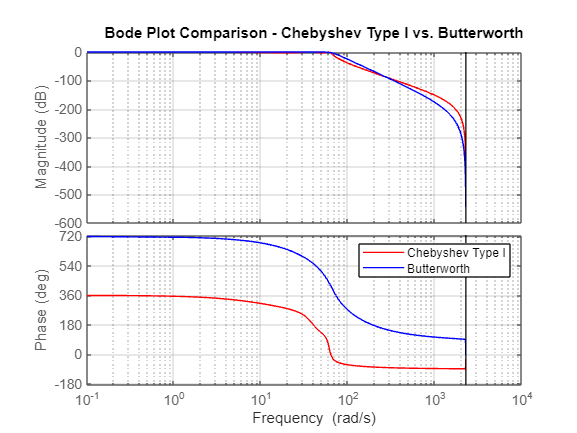


% Plot the Bode plots of Chebyshev Type I and Butterworth filters
figure;
bode(sos_chebyshev, 'r', sos_butterworth, 'b');
title('Bode Plot Comparison - Chebyshev Type I vs. Butterworth');
legend('Chebyshev Type I', 'Butterworth');
grid on;

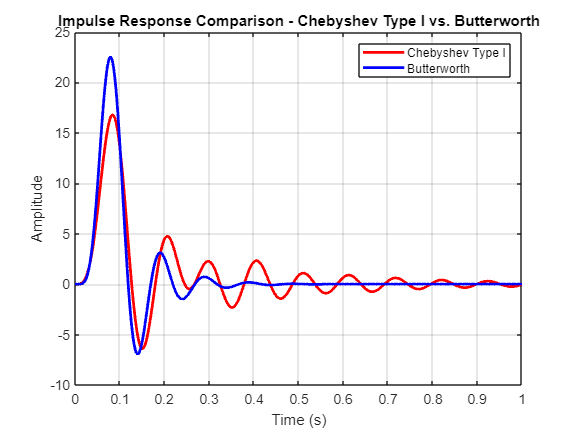


% Define the time vector for 1 second
t = 0:1/Fs:1;

% Compute the impulse response of the Chebyshev Type I filter
impulse_response_chebyshev = impulse(sos_chebyshev, t);

% Compute the step response of the Chebyshev Type I filter
step_response_chebyshev = step(sos_chebyshev, t);

% Compute the impulse response and step response of the Butterworth filter
impulse_response_butterworth = impulse(sos_butterworth, t);
step_response_butterworth = step(sos_butterworth, t);

% Plot the impulse response and step response of both filters on the same graph
figure;
plot(t, impulse_response_chebyshev, 'r', 'LineWidth', 2, 'DisplayName', 'Chebyshev Type I');
hold on;
plot(t, impulse_response_butterworth, 'b', 'LineWidth', 2, 'DisplayName', 'Butterworth');
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response Comparison - Chebyshev Type I vs. Butterworth');
legend('Location', 'northeast');
grid on;

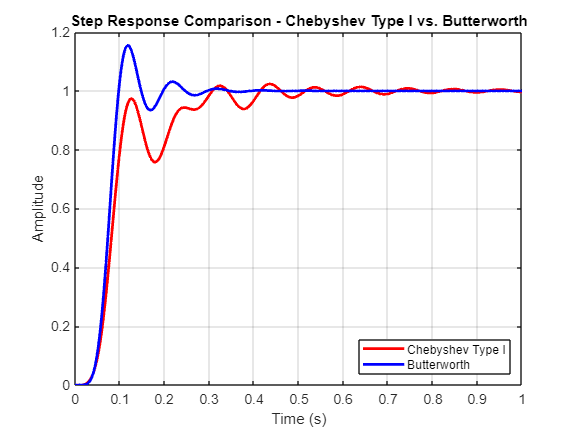


figure;
plot(t, step_response_chebyshev, 'r', 'LineWidth', 2, 'DisplayName', 'Chebyshev Type I');
hold on;
plot(t, step_response_butterworth, 'b', 'LineWidth', 2, 'DisplayName', 'Butterworth');
xlabel('Time (s)');
ylabel('Amplitude');
title('Step Response Comparison - Chebyshev Type I vs. Butterworth');
legend('Location', 'southeast');
grid on;